# Open loop analysis

## Create models

% Generate models
altitude = 40000;
velocity = 300;

model = find_f16_dynamics('LIN_F16Block_', 0, altitude, velocity, 5);

% Display the models
model.ss_lon

ans =
 
  A = 
                     v       alpha       theta           q     delta_e
   v          -0.08894       -10.7      -32.17      -3.977    -0.07104
   alpha    -0.0005042    -0.05167  -3.989e-14      0.9792  -0.0002308
   theta             0           0           0           1           0
   q         1.228e-18     -0.6256           0     -0.2485    -0.01541
   delta_e           0           0           0           0       -20.2
 
  B = 
            delta_e
   v              0
   alpha          0
   theta          0
   q              0
   delta_e     20.2
 
  C = 
                v    alpha    theta        q  delta_e
   v            1        0        0        0        0
   alpha        0        1        0        0        0
   theta        0        0        1        0        0
   q            0        0        0        1        0
 
  D = 
          delta_e
   v            0
   alpha        0
   theta        0
   q            0
 
Continuous-time state-space model.



model.ss_lon_ac

ans =
 
  A = 
                   v       alpha       theta           q
   v        -0.08894       -10.7      -32.17      -3.977
   alpha  -0.0005042    -0.05167  -3.989e-14      0.9792
   theta           0           0           0           1
   q       1.228e-18     -0.6256           0     -0.2485
 
  B = 
             delta_e
   v        -0.07104
   alpha  -0.0002308
   theta           0
   q        -0.01541
 
  C = 
              v  alpha  theta      q
   v          1      0      0      0
   alpha      0      1      0      0
   theta      0      0      1      0
   q          0      0      0      1
 
  D = 
          delta_e
   v            0
   alpha        0
   theta        0
   q            0
 
Continuous-time state-space model.



model.ss_lat

ans =
 
  A = 
                 beta        phi          p          r    delta_a    delta_r
   beta      -0.04905    0.08741     0.5803    -0.8129  4.181e-05  0.0001227
   phi              0          0          1     0.7105          0          0
   p           -2.547          0    -0.2594      0.151    -0.0444   -0.00523
   r            -0.59          0    0.02607    -0.1313   0.002184  -0.004975
   delta_a          0          0          0          0      -20.2          0
   delta_r          0          0          0          0          0      -20.2
 
  B = 
              u1    u2
   beta        0     0
   phi         0     0
   p           0     0
   r           0     0
   delta_a  20.2     0
   delta_r     0  20.2
 
  C = 
            beta      phi        p        r  delta_a  delta_r
   beta        1        0        0        0        0        0
   phi         0        1        0        0        0        0
   p           0        0        1        0        0        0
   r           0   

model.ss_lat_ac

ans =
 
  A = 
             beta       phi         p         r
   beta  -0.04905   0.08741    0.5803   -0.8129
   phi          0         0         1    0.7105
   p       -2.547         0   -0.2594     0.151
   r        -0.59         0   0.02607   -0.1313
 
  B = 
           delta_a    delta_r
   beta  4.181e-05  0.0001227
   phi           0          0
   p       -0.0444   -0.00523
   r      0.002184  -0.004975
 
  C = 
         beta   phi     p     r
   beta     1     0     0     0
   phi      0     1     0     0
   p        0     0     1     0
   r        0     0     0     1
 
  D = 
         delta_a  delta_r
   beta        0        0
   phi         0        0
   p           0        0
   r           0        0
 
Continuous-time state-space model.



## Motion characteristics

### Longitudinal motion

damp(model.ss_lon_ac);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.17e-02 + 1.23e-01i     3.22e-01       1.30e-01         2.40e+01    
 -4.17e-02 - 1.23e-01i     3.22e-01       1.30e-01         2.40e+01    
 -1.53e-01 + 7.62e-01i     1.97e-01       7.77e-01         6.54e+00    
 -1.53e-01 - 7.62e-01i     1.97e-01       7.77e-01         6.54e+00    


### Lateral motion

% All the eitgen values for lateral motion are complex in this flight
% conditon. I expeted to find two real eigenvalues.
% I'll use the 15000ft/500fps flight condition for the lateral motion part
% of this assignment.
damp(model.ss_lat_ac);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.68e-01 + 1.57e-01i     7.32e-01       2.30e-01         5.95e+00    
 -1.68e-01 - 1.57e-01i     7.32e-01       2.30e-01         5.95e+00    
 -5.18e-02 + 9.78e-01i     5.29e-02       9.80e-01         1.93e+01    
 -5.18e-02 - 9.78e-01i     5.29e-02       9.80e-01         1.93e+01    


### Short period oscillation

wn_sp = 7.77e-1;
zeta_sp = 1.97e-1;
t_end = 40

t_end = 40


[p_sp, t12_sp] = calc_periodic_properties(wn_sp, zeta_sp)

p_sp = 8.0865

t12_sp = 4.4268

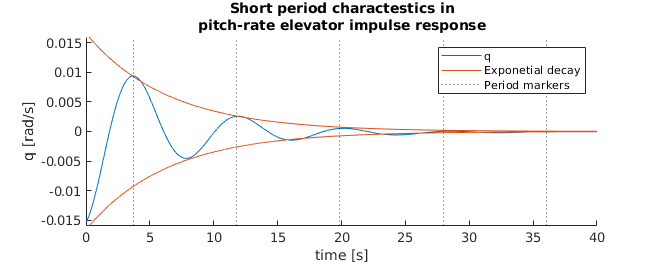

[y, t] = impulse(model.ss_lon_ac, 0:0.001:t_end);
y = y(:, 4);

[peaks, locs] = findpeaks(y);
dp_idx = 1;
dp = t(locs(dp_idx));

yy=0.5.^(t./t12_sp)*0.0166;

clf
hold on
plot(t, y)
plot(t, yy, "Color", [0.8500, 0.3250, 0.0980])
for i = -2:5
    xline(i*p_sp+dp, 'k:')
end
plot(t, -yy, "Color", [0.8500, 0.3250, 0.0980])

xlabel('time [s]')
ylabel('q [rad/s]')
title({'Short period charactestics in','pitch-rate elevator impulse response'})
set(gcf,'units','points','position',[0,0, 500, 200])
legend("q", "Exponetial decay", "Period markers")
xlim([0, t_end]);
ylim([-0.016, 0.016])
hold off

### Phugoid oscilation

wn_ph = 1.30e-1;
zeta_ph = 3.22e-1;
t_end = 200;

[p_ph, t12_ph] = calc_periodic_properties(wn_ph, zeta_ph)

p_ph = 48.3322

t12_ph = 15.6316

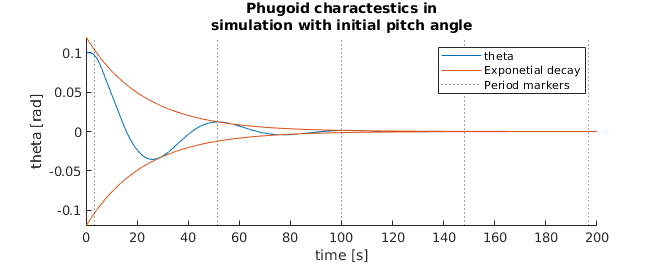

x0 = [0, 0, 0.1, 0];
[y, t] = initial(model.ss_lon_ac, x0, 0:0.001:t_end);
y = y(:, 3);

yy=0.5.^(t./t12_ph)*0.12;

[peaks, locs] = findpeaks(y);
dp_idx = 1;
dp = t(locs(dp_idx));

clf
hold on
plot(t, y)
plot(t, yy, "Color", [0.8500, 0.3250, 0.0980])
for i = -4:5
    xline(i*p_ph+dp, 'k:')
end
plot(t, -yy, "Color", [0.8500, 0.3250, 0.0980])

xlabel('time [s]')
ylabel('theta [rad]')
title({'Phugoid charactestics in','simulation with initial pitch angle'})
set(gcf,'units','points','position',[0,0, 500, 200])
legend("theta", "Exponetial decay", "Period markers")
xlim([0, t_end]);
ylim([-0.12 0.12])
hold off

### New model

altitude = 15000;
velocity = 500;
model_2 = find_f16_dynamics('LIN_F16Block_', 0, altitude, velocity, 5);

model_2.ss_lat_ac

ans =
 
  A = 
            beta      phi        p        r
   beta  -0.2022  0.06414  0.07827  -0.9919
   phi         0        0        1   0.0781
   p      -22.92        0   -2.254   0.5408
   r       6.005        0  -0.0404  -0.3146
 
  B = 
           delta_a    delta_r
   beta  0.0001724  0.0005058
   phi           0          0
   p       -0.4623    0.05686
   r      -0.02437   -0.04687
 
  C = 
         beta   phi     p     r
   beta     1     0     0     0
   phi      0     1     0     0
   p        0     0     1     0
   r        0     0     0     1
 
  D = 
         delta_a  delta_r
   beta        0        0
   phi         0        0
   p           0        0
   r           0        0
 
Continuous-time state-space model.



damp(model_2.ss_lat_ac);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.13e-02                 1.00e+00       1.13e-02         8.88e+01    
 -2.12e+00                 1.00e+00       2.12e+00         4.72e-01    
 -3.20e-01 + 2.74e+00i     1.16e-01       2.76e+00         3.13e+00    
 -3.20e-01 - 2.74e+00i     1.16e-01       2.76e+00         3.13e+00    


### Dutch roll

wn_dr = 2.76;
zeta_dr = 1.16e-1;
t_end = 15;

[p_dr, t12_dr] = calc_periodic_properties(wn_dr, zeta_dr)

p_dr = 2.2765

t12_dr = 2.1442

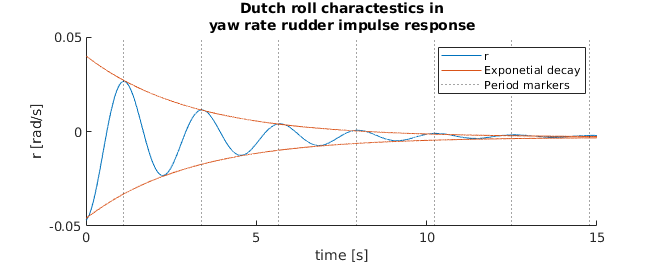

[y, t] = impulse(model_2.ss_lat_ac, 0:0.001:t_end);
y = y(:, 4, 2);

yy=0.5.^(t./t12_dr)*0.0430;
dyy = -0.0030;

[peaks, locs] = findpeaks(y);
dp_idx = 1;
dp = t(locs(dp_idx));

clf
hold on
plot(t, y)
plot(t, yy+dyy, "Color", [0.8500, 0.3250, 0.0980])
for i = -2:7
    xline(i*p_dr+dp, 'k:')
end
plot(t, -yy+dyy, "Color", [0.8500, 0.3250, 0.0980])
xlabel('time [s]')
ylabel('r [rad/s]')
title({'Dutch roll charactestics in','yaw rate rudder impulse response'})
set(gcf,'units','points','position',[0,0, 500, 200])
legend("r", "Exponetial decay", "Period markers")
xlim([0, t_end]);
ylim([-0.05, 0.05]);
hold off

### Aperiodic roll

wn_ap = 2.12

wn_ap = 2.1200

tau_ap = 4.72e-1

tau_ap = 0.4720

t12_ap = log(2) * tau_ap

t12_ap = 0.3272

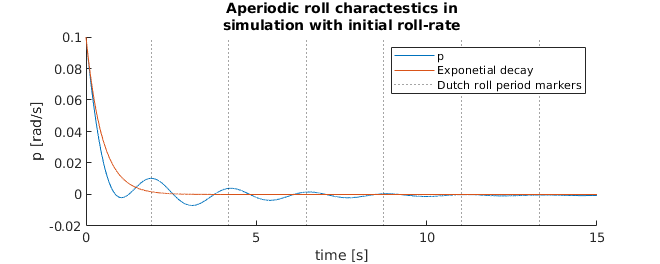

t_end = 15;
x0 = [0, 0, 0.1, 0];
[y, t] = initial(model_2.ss_lat_ac, x0, 0:0.001:t_end);

y = y(:, 3);

yy=0.5.^(t./t12_ap)*0.1;
dyy = 0.;

[peaks, locs] = findpeaks(y);
dp_idx = 1;
dp = t(locs(dp_idx));

clf
hold on
plot(t, y)
plot(t, yy+dyy, "Color", [0.8500, 0.3250, 0.0980])
for i = -2:5
    xline(i*p_dr+dp, 'k:')
end
xlabel('time [s]')
ylabel('p [rad/s]')
title({'Aperiodic roll charactestics in','simulation with initial roll-rate'})
set(gcf,'units','points','position',[0,0, 500, 200])
legend("p", "Exponetial decay", "Dutch roll period markers")
xlim([0, t_end]);
% ylim([-0.05, 0.05]);
hold off

### Spiral

wn_si = 1.13e-2

wn_si = 0.0113

tau_si = 8.88e1

tau_si = 88.8000

t12_si = log(2) * tau_si

t12_si = 61.5515

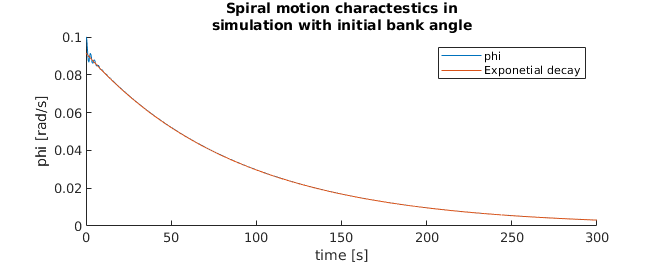


t_end = 300;
x0 = [0, 0.1, 0, 0];
[y, t] = initial(model_2.ss_lat_ac, x0, t_end);

yy=0.5.^(t./t12_si)*0.0915;
dyy = 0.;

clf
hold on
plot(t, y(:, 2))
plot(t, yy+dyy, "Color", [0.8500, 0.3250, 0.0980])

xlabel('time [s]')
ylabel('phi [rad/s]')
title({'Spiral motion charactestics in','simulation with initial bank angle'})
set(gcf,'units','points','position',[0,0, 500, 200])
legend("phi", "Exponetial decay")
xlim([0, t_end]);
% ylim([-0.05, 0.05]);
hold off